# HW01: Plotting data and its first and second derivatives 

**Here I used MATLAB "diff" function to find the derivative of the data and again I used the diff function on the first derivative to obtain the second derivative and I plotted them on one graph, then I plotted y(x) and y'(x) again on another graph in order to be able to distinguish them. **

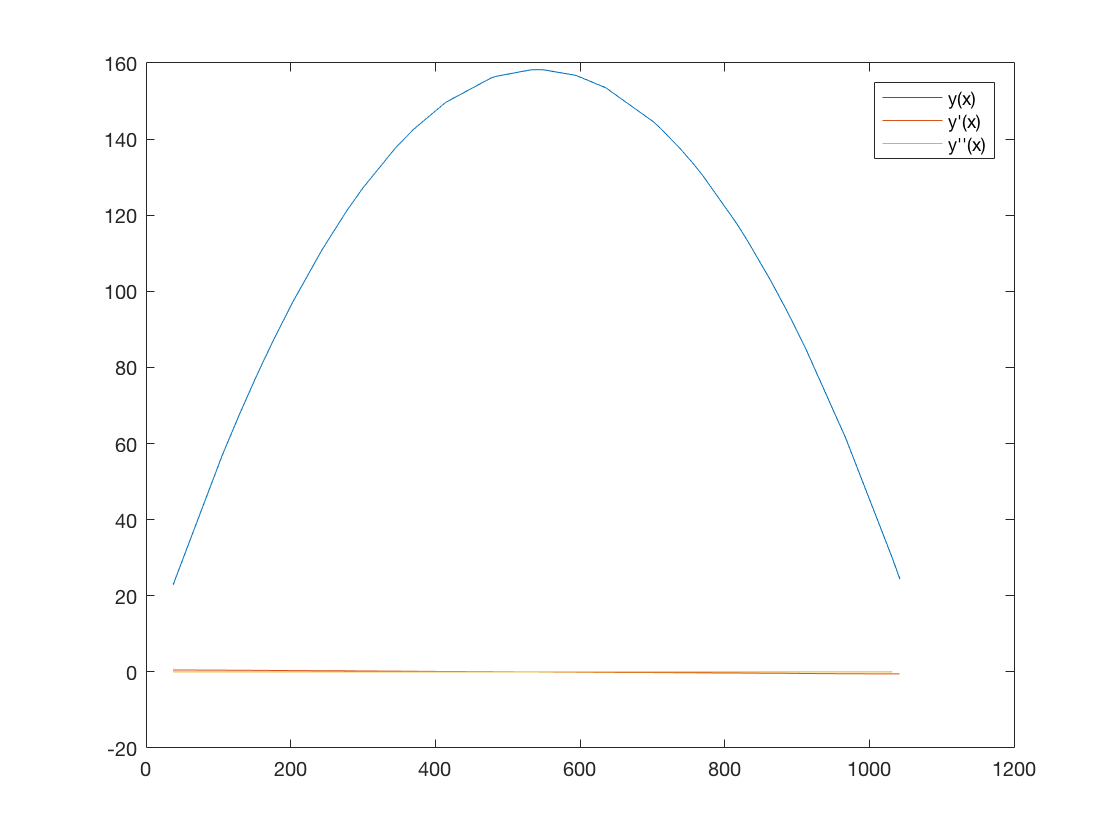

data=load ('derdata.mat');
x=data.X;
y=data.Y;
n=length(x);

yp = diff(y(:))./diff( x(:));
xp= x(1:n-1);
np=length(xp);
ypp= diff( yp(:))./diff( xp(:));
xpp=xp(1:np-1);
plot(x,y,xp,yp,xpp,ypp);
legend('y(x)','y''(x)','y''''(x)')

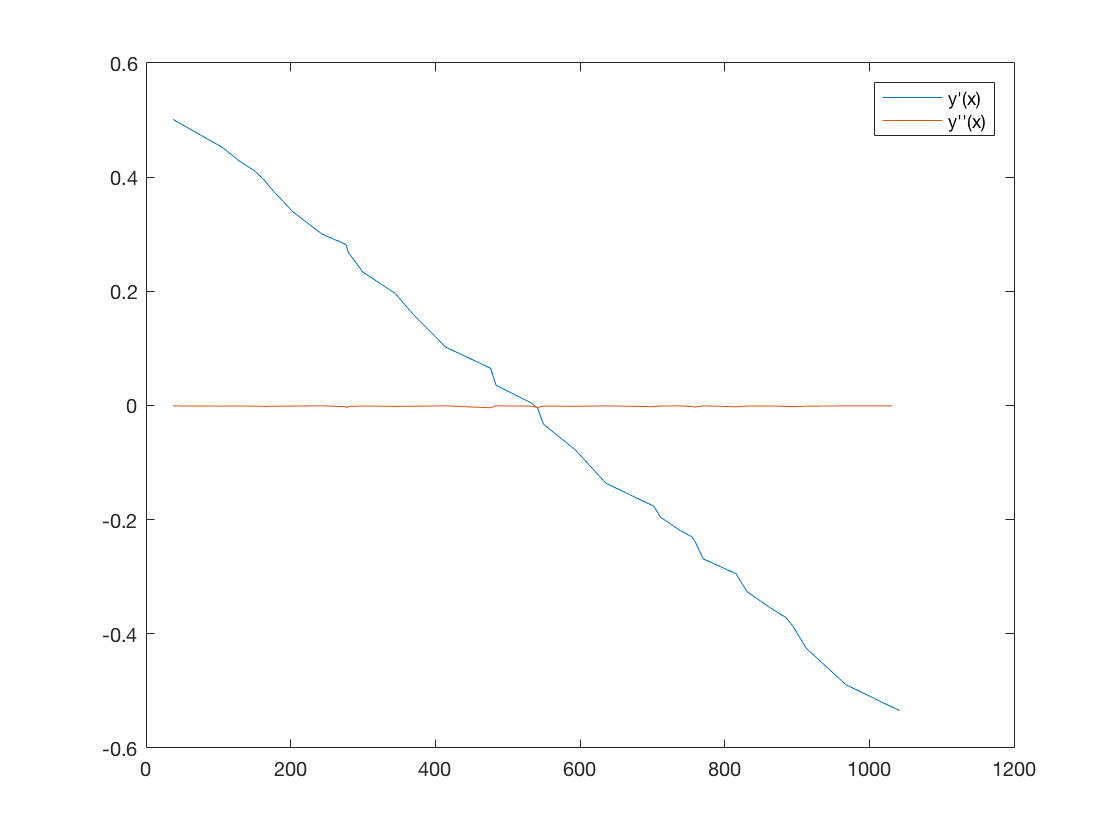

plot (xp,yp,xpp,ypp);
legend('y''(x)','y''''(x)')